LionsVideo = VideoReader("Lions.mp4")

LionsVideo =   VideoReader with properties:

   General Properties:
            Name: 'Lions.mp4'
            Path: 'C:\Users\21692\Desktop\Etudes en France\IMT\FISEA2\Computer Vision\Project\Lions'
        Duration: 27.6526
     CurrentTime: 0
       NumFrames: <Calculating...> learn more

   Video Properties:
           Width: 1920
          Height: 1080
       FrameRate: 23.9760
    BitsPerPixel: 24
     VideoFormat: 'RGB24'



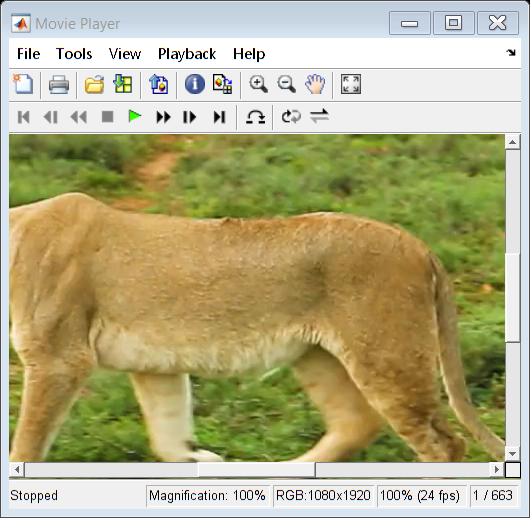

implay("Lions.mp4")

frame_1 = read(LionsVideo,569);
frame_30 = read(LionsVideo,150);
frame_122 = read(LionsVideo,290);
frame_200 = read(LionsVideo,3);
[Th,maskedRGBImage] = createMaskLions(frame_1,i);
[BW,maskedImage] = segmentImageLionsFirst(maskedRGBImage);
    
BW = filterRegionsLionsOne(BW,569);

[BW,maskedRGBImage] = createMaskLions(maskedRGB);

numFrames_Lions= LionsVideo.NumFrames;
v_seg= VideoWriter("Boxed_Lioness","MPEG-4");

v_seg.FrameRate = LionsVideo.FrameRate;
v_seg_comb.FrameRate = LionsVideo.FrameRate;
open(v_seg);
bboxes = [];
idxes = [];
for i = 1 : numFrames_Lions-1
    frame = read(LionsVideo,i);
    idx = string(i);
    while strlength(idx) ~= 3
        idx = append("0",idx);
    end
    %imwrite(frame,"Lions-"+idx+".png");
    [Th,maskedRGBImage] = createMaskLions(frame,i);
    [BW,maskedImage] = segmentImageLionsFirst(maskedRGBImage);
    
    BW = filterRegionsLionsOne(BW,i);
    %imwrite(BW,"MaskedLions-"+idx+".png");
    props = regionprops("table",BW,"BoundingBox");
    BoxedLions =insertShape(frame,"Rectangle",props.BoundingBox,"LineWidth",4,"Color","black");
    writeVideo(v_seg, BoxedLions);
    bboxes = [bboxes;props];
    idxes = [idxes;i];

end
close(v_seg);

idxes

coords=[];
coords.frames= idxes;
coords.x1 = bboxes.BoundingBox(:,1);
coords.y1 = bboxes.BoundingBox(:,2);
coords.w = bboxes.BoundingBox(:,3);
coords.h = bboxes.BoundingBox(:,4);

coords = struct2table(coords);
writetable(coords,"coords_Lioness.txt");

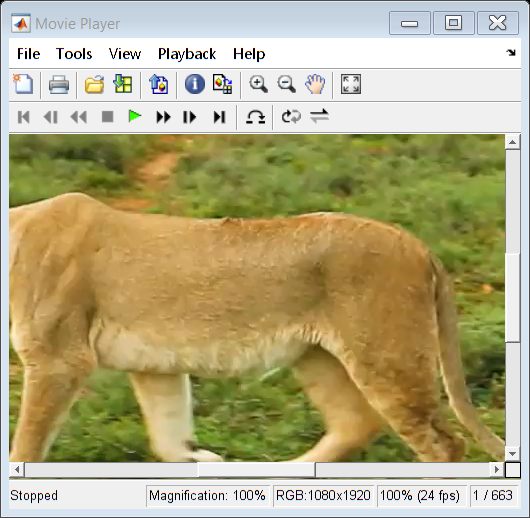

implay("Boxed_Lioness.mp4")

[rows,cols] = size(imread("ThresholdedLions-170.jpg"))

imtool("ThresholdedLions-215.jpg")